# Homework 9

Ross Smyth

clear, clc, close all

## Problem 1

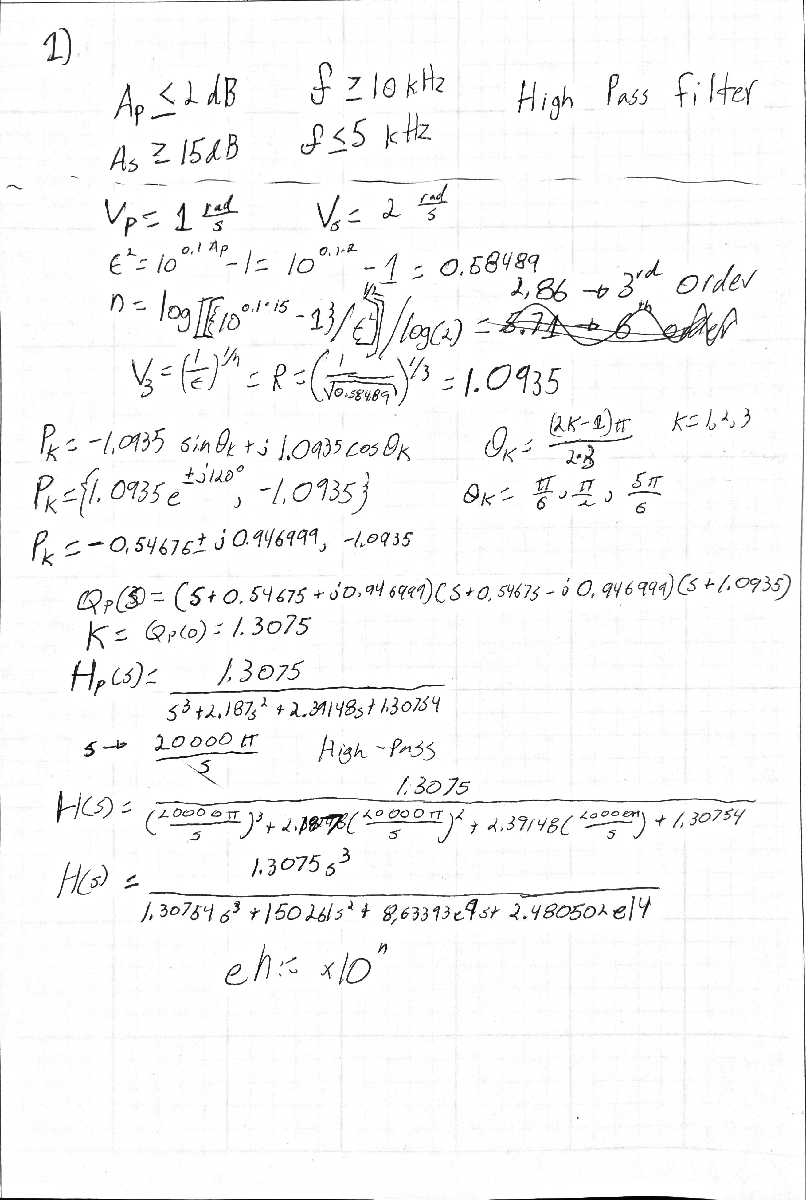

prob_1 = tf([1.30754, 0, 0, 0], [1.30754, 150251, 8.63393E9, 2.480502E14]);

% Verification of attenuation.
pass_1 = freqresp(prob_1, 10000, 'Hz');
stop_1 = freqresp(prob_1, 5000, 'Hz');

mag2db(abs(pass_1)) + 2 > 0

ans = logical
   1


mag2db(abs(stop_1)) + 15 < 0

ans = logical
   1


filter_in =
 
                    1.308 s^3
  ----------------------------------------------
  1.308 s^3 + 150251 s^2 + 8.634e09 s + 2.481e14
 
Continuous-time transfer function.



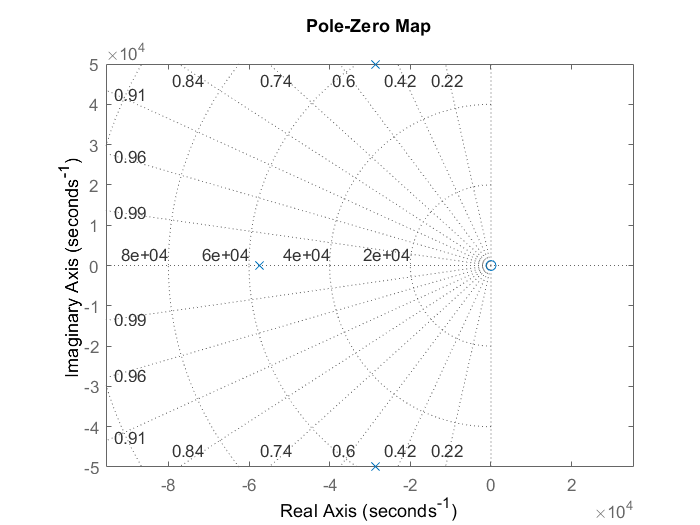

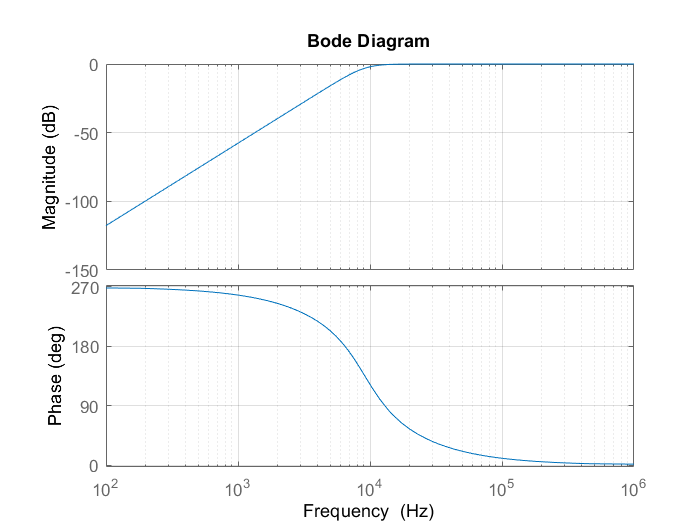


output(prob_1);

## Problem 2

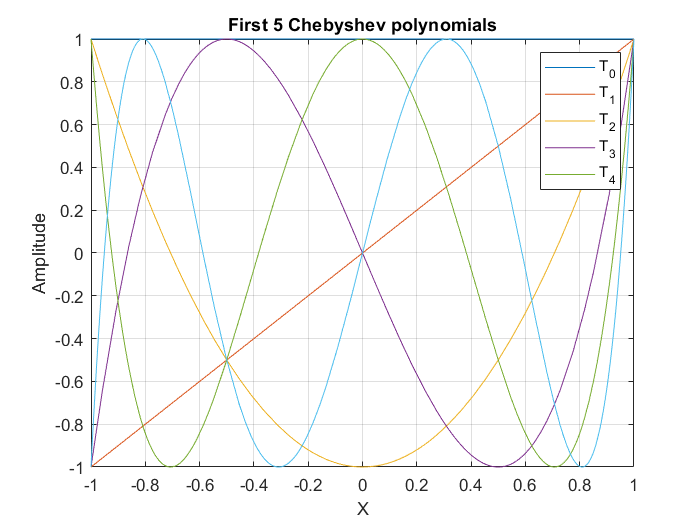

syms x

fplot(chebyshevT(0:5,x))
axis([-1 1 -1 1])
title('First 5 Chebyshev polynomials')
xlabel('X')
ylabel('Amplitude')
grid
legend('T_0', 'T_1', 'T_2', 'T_3', 'T_4')

Looking at these polynomials, they all have the same maximum values over the interval of [-1, 1]. This means that the hieght of their ripples over this range is the same, and therefore are equiripple.

## Problem 3

Function that makes the outputs is at the bottom of the file.

### a. 

filter_in =
 
                                                    
                                            7.149e71
                                                    
  ---------------------------------------------------------------------------------------------
                                                                                               
  s^14 + 1.212e06 s^13 + 7.34e11 s^12 + 2.939e17 s^11 + 8.674e22 s^10 + 1.993e28 s^9           
                                                                                               
          + 3.671e33 s^8 + 5.507e38 s^7 + 6.756e43 s^6 + 6.749e48 s^5 + 5.406e53 s^4           
                                                                                               
                                          + 3.371e58 s^3 + 1.549e63 s^2 + 4.707e67 s + 7.149e71
                                                                                               
 
Continuous-time transfer function.



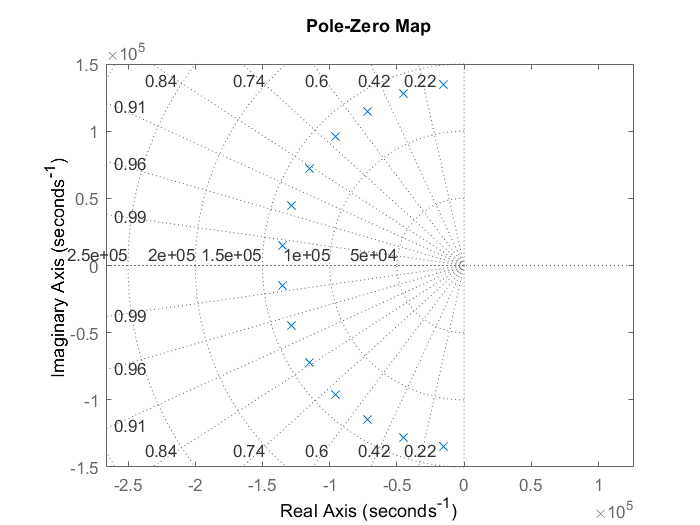

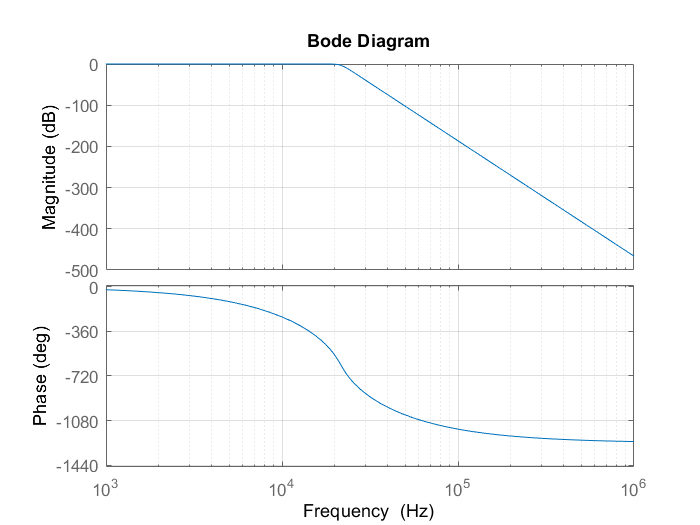

Ap = 1; % dB attenuation
As = 40; % dB pass ripple

% a
[n, wn]    = buttord(20000 * 2 * pi, 30000 * 2 * pi, Ap, As, 's');
[z, p, k]  = butter(n, wn, 'low', 's');
[num, den] = zp2tf(z, p, k);
filter_a   = tf(num, den);
output(filter_a)

### b.

filter_in =
 
                                                    
                                             1.52e34
                                                    
  ---------------------------------------------------------------------------------------------
                                                                                               
  s^7 + 1.16e05 s^6 + 3.436e10 s^5 + 2.835e15 s^4 + 3.385e20 s^3 + 1.719e25 s^2 + 8.414e29 s   
                                                                                               
                                                                                      + 1.52e34
                                                                                               
 
Continuous-time transfer function.



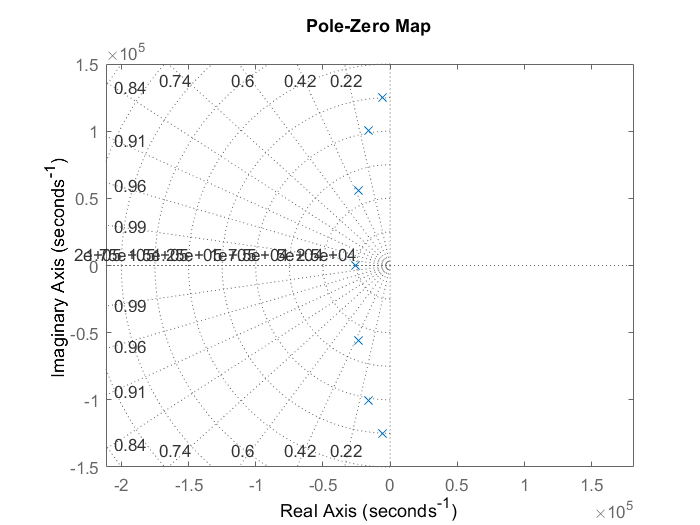

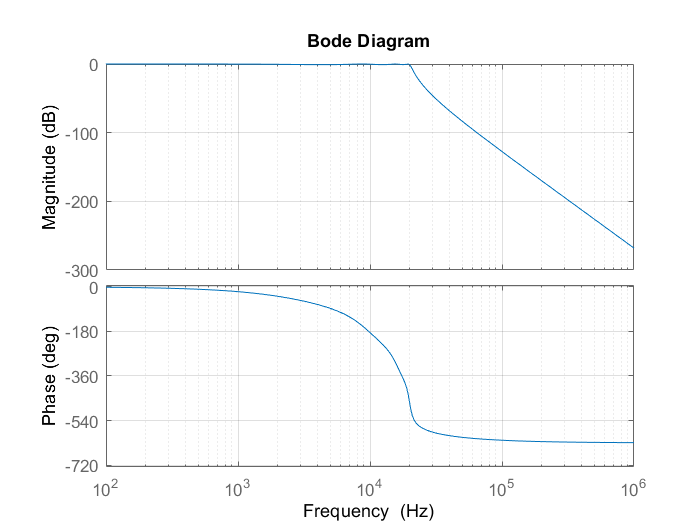

[n, wp]    = cheb1ord(20000 * 2 * pi, 30000 * 2 * pi, Ap, As, 's');
[z, p, k]  = cheby1(n, Ap, wp, 'low', 's');
[num, den] = zp2tf(z, p, k);
filter_b   = tf(num, den);
output(filter_b)

### c.

filter_in =
 
                                                  
                                              s^14
                                                  
  ---------------------------------------------------------------------------------------------
                                                                                               
  s^14 + 1.559e06 s^13 + 1.216e12 s^12 + 6.268e17 s^11 + 2.381e23 s^10 + 7.04e28 s^9           
                                                                                               
          + 1.669e34 s^8 + 3.223e39 s^7 + 5.089e44 s^6 + 6.543e49 s^5 + 6.747e54 s^4           
                                                                                               
                                          + 5.415e59 s^3 + 3.203e64 s^2 + 1.252e69 s + 2.449e73
                                                                                               
 
Continuous-time transfer function.



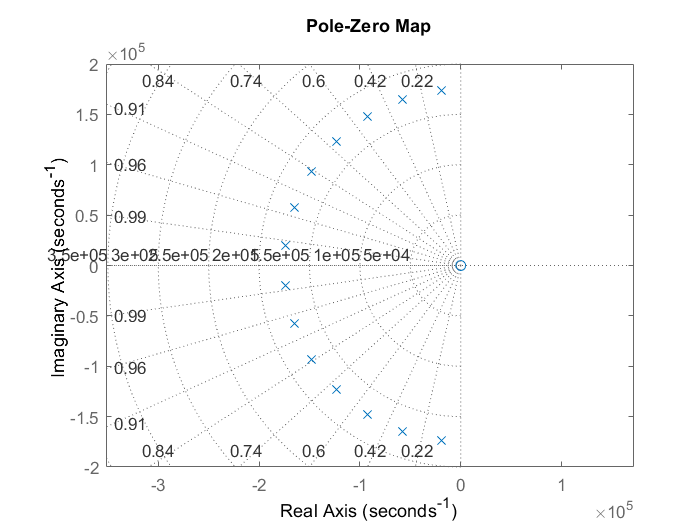

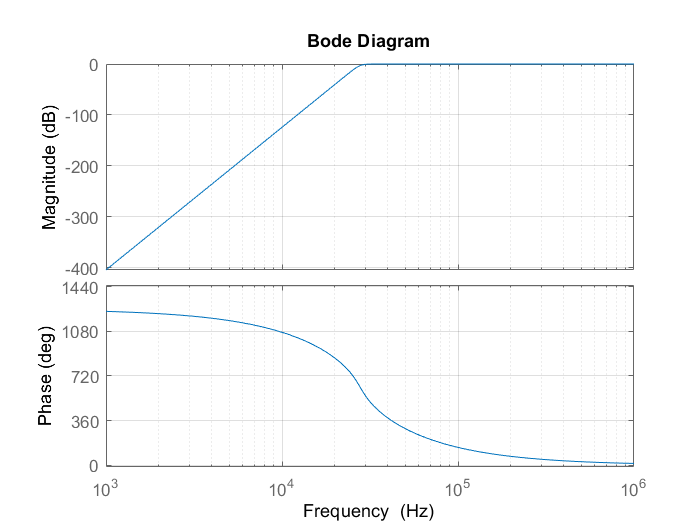

[n, wn]    = buttord(30000 * 2 * pi, 20000 * 2 * pi, Ap, As, 's');
[z, p, k]  = butter(n, wn, 'high', 's');
[num, den] = zp2tf(z, p, k);
filter_c   = tf(num, den);
output(filter_c)

### d.

filter_in =
 
                                                  
                                               s^7
                                                  
  ---------------------------------------------------------------------------------------------
                                                                                               
  s^7 + 1.312e06 s^6 + 6.348e11 s^5 + 2.961e17 s^4 + 5.874e22 s^3 + 1.686e28 s^2 + 1.348e33 s  
                                                                                               
                                                                                     + 2.753e38
                                                                                               
 
Continuous-time transfer function.



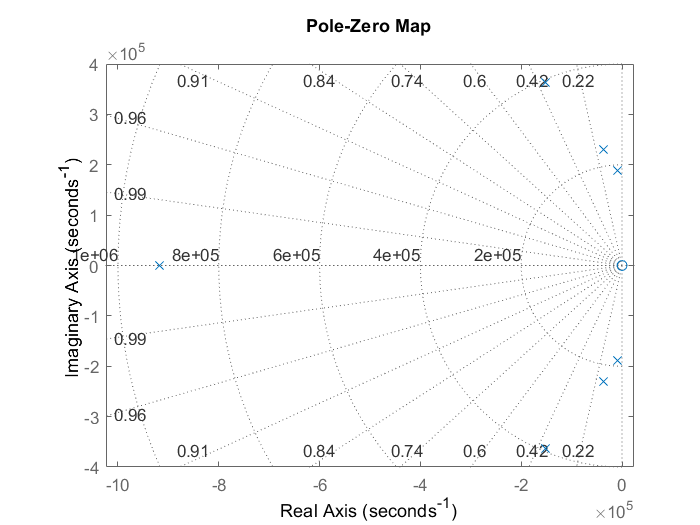

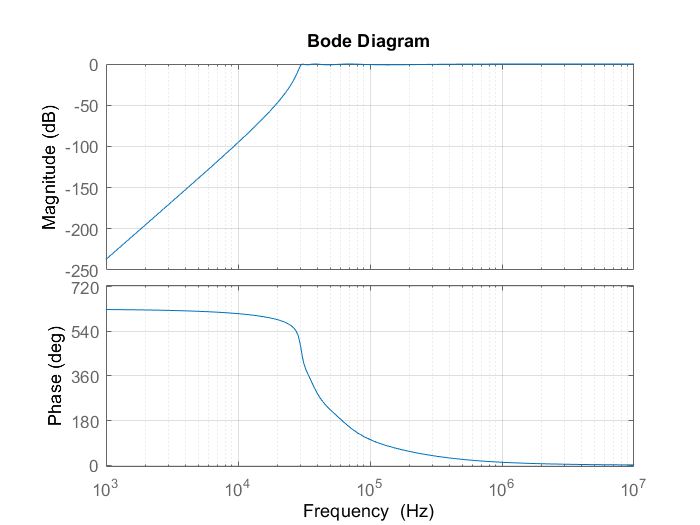

[n, wp]    = cheb1ord(30000 * 2 * pi, 20000 * 2 * pi, Ap, As, 's');
[z, p, k]  = cheby1(n, Ap, wp, 'high', 's');
[num, den] = zp2tf(z, p, k);
filter_d   = tf(num, den);
output(filter_d)

### e.

filter_in =
 
                                                      
                                          1.456e34 s^7
                                                      
  ---------------------------------------------------------------------------------------------
                                                                                               
  s^14 + 3.413e05 s^13 + 1.135e11 s^12 + 2.256e16 s^11 + 4.093e21 s^10 + 5.464e26 s^9          
                                                                                               
          + 6.588e31 s^8 + 6.167e36 s^7 + 5.202e41 s^6 + 3.406e46 s^5 + 2.015e51 s^4           
                                                                                               
                                          + 8.766e55 s^3 + 3.483e60 s^2 + 8.268e64 s + 1.913e69
                                                                                               
 
Continuous-time transfer function.



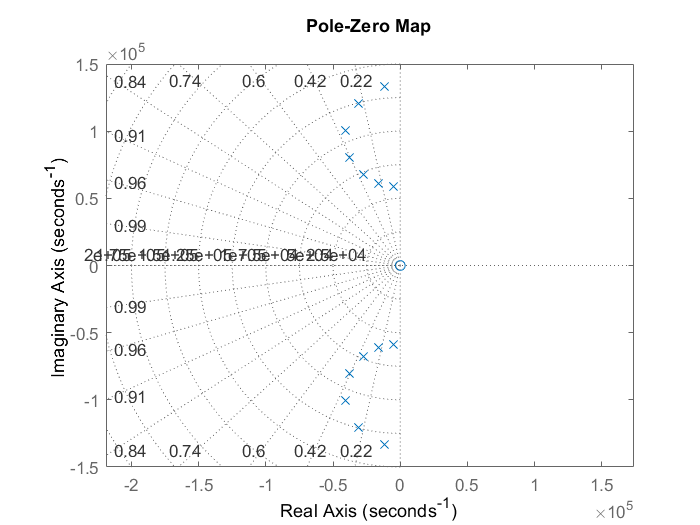

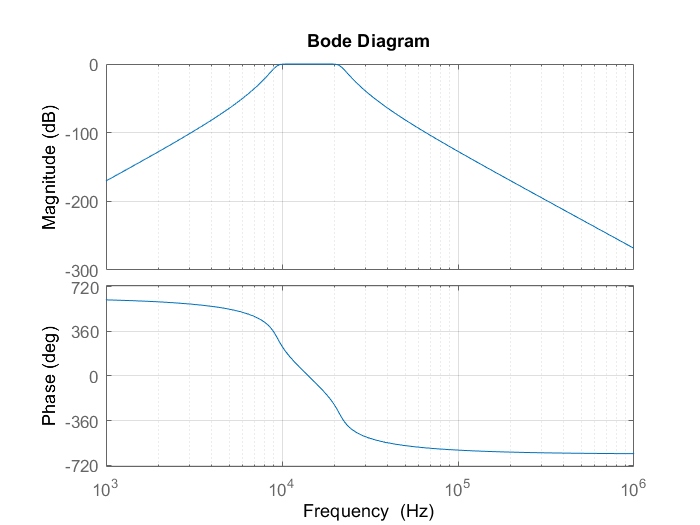

[n, wn]    = buttord([10000 * 2 * pi, 20000 * 2 * pi], [5000 * 2 * pi, 30000 * 2 * pi], Ap, As, 's');
[z, p, k]  = butter(n, wn, 'bandpass', 's');
[num, den] = zp2tf(z, p, k);
filter_e   = tf(num, den);
output(filter_e)

### f.

filter_in =
 
                                                       
                                           1.203e23 s^5
                                                       
  -----------------------------------------------------------------------------------------------
                                                                                                 
  s^10 + 5.886e04 s^9 + 4.615e10 s^8 + 2.101e15 s^7 + 7.904e20 s^6 + 2.595e25 s^5 + 6.241e30 s^4 
                                                                                                 
                                           + 1.31e35 s^3 + 2.271e40 s^2 + 2.288e44 s + 3.069e49  
                                                                                                 
 
Continuous-time transfer function.



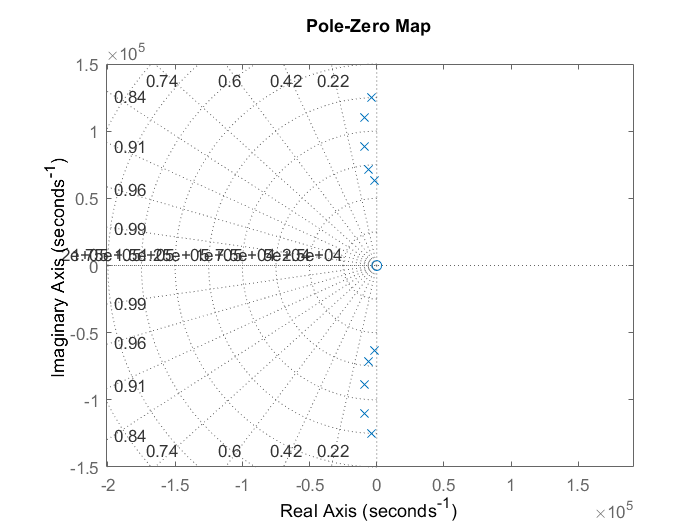

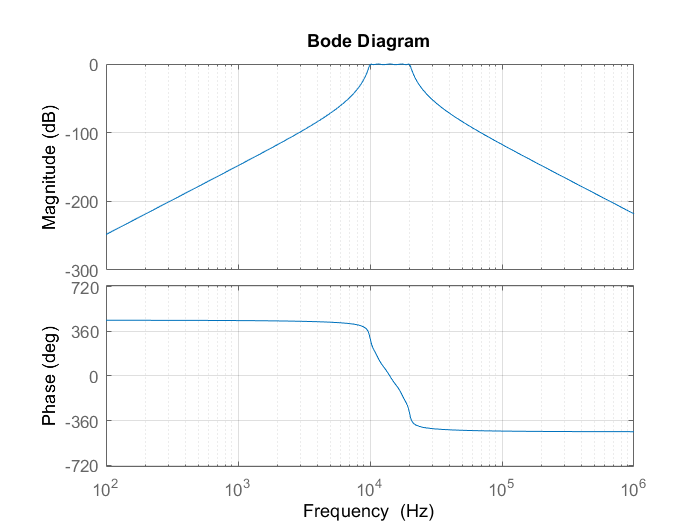

[n, wp]    = cheb1ord([10000 * 2 * pi, 20000 * 2 * pi], [5000 * 2 * pi, 30000 * 2 * pi], Ap, As, 's');
[z, p, k]  = cheby1(n, Ap, wp, 'bandpass', 's');
[num, den] = zp2tf(z, p, k);
filter_f   = tf(num, den);
output(filter_f)

### g.

filter_in =
 
                                                                                                  
  s^14 + 5.527e10 s^12 + 1.309e21 s^10 + 1.723e31 s^8 + 1.36e41 s^6 + 6.444e50 s^4 + 1.696e60 s^2 
                                                                                                  
                                                                                     + 1.913e69   
                                                                                                  
  -------------------------------------------------------------------------------------------------
                                                                                                   
  s^14 + 5.452e05 s^13 + 2.039e11 s^12 + 5.187e16 s^11 + 1.034e22 s^10 + 1.598e27 s^9              
                                                                                                   
          + 1.99e32 s^8 + 1.969e37 s^7 + 1.572e42 s^6 + 9.961e46 s^5 + 5.087e51 s^4 + 2.016

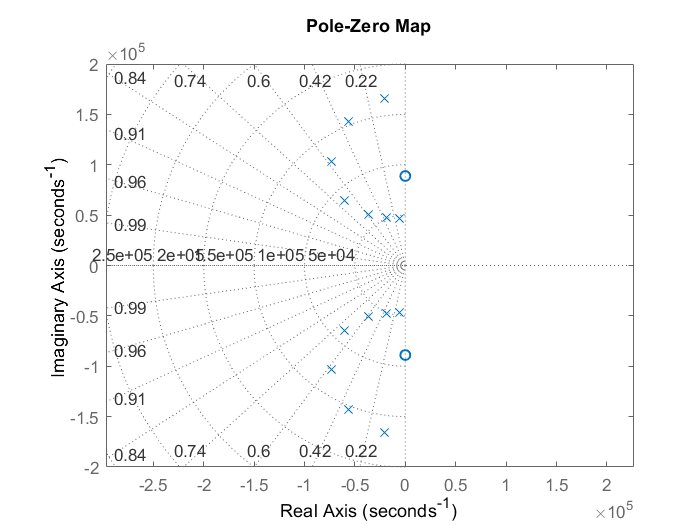

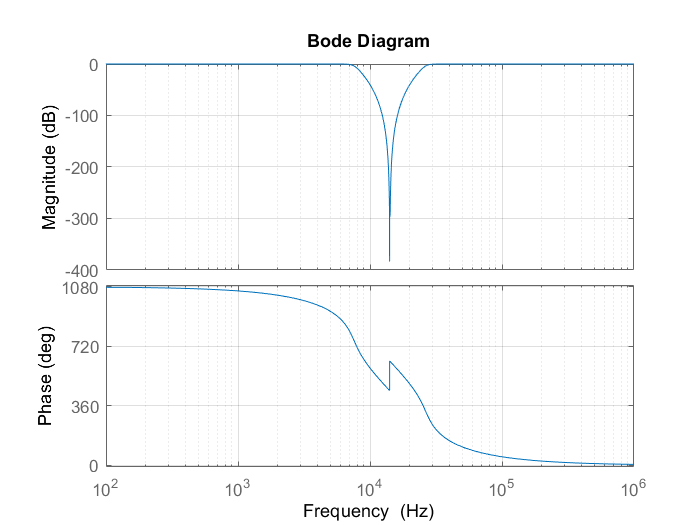

[n, wn]    = buttord([5000 * 2 * pi, 30000 * 2 * pi], [10000 * 2 * pi, 20000 * 2 * pi], Ap, As, 's');
[z, p, k]  = butter(n, wn, 'stop', 's');
[num, den] = zp2tf(z, p, k);
filter_g   = tf(num, den);
output(filter_g)

### h.

filter_in =
 
                                                                                      
           s^10 + 3.948e10 s^8 + 6.234e20 s^6 + 4.922e30 s^4 + 1.943e40 s^2 + 3.069e49
                                                                                      
  ---------------------------------------------------------------------------------------------
                                                                                               
  s^10 + 6.929e05 s^9 + 2.1e11 s^8 + 6.521e16 s^7 + 8.186e21 s^6 + 1.495e27 s^5 + 6.463e31 s^4 
                                                                                               
                                          + 4.065e36 s^3 + 1.034e41 s^2 + 2.693e45 s + 3.069e49
                                                                                               
 
Continuous-time transfer function.



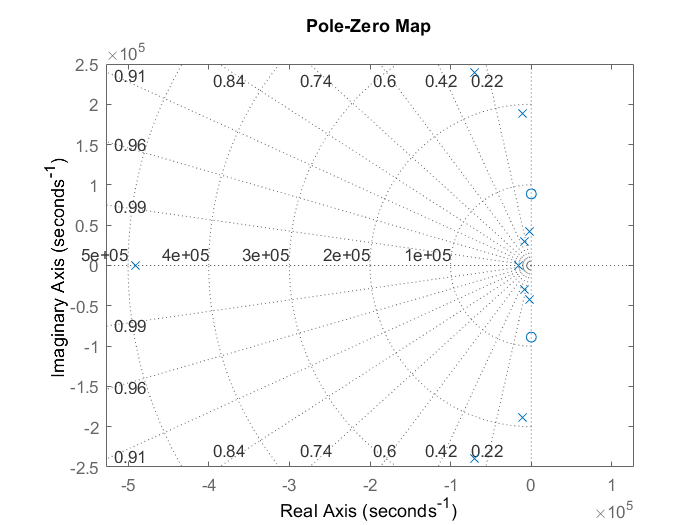

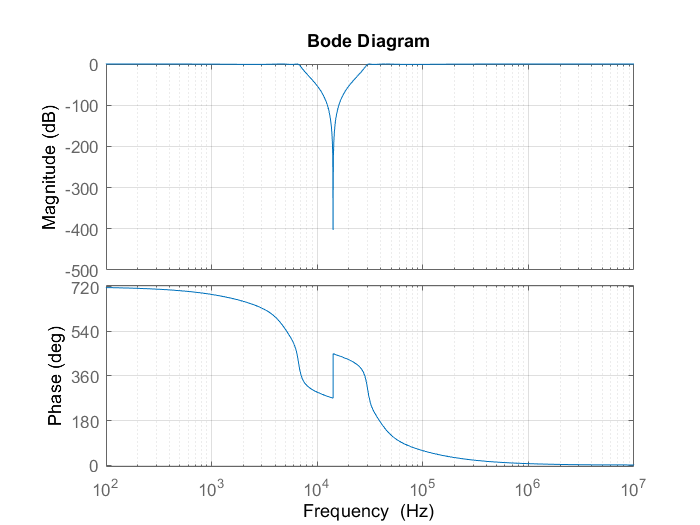

[n, wp]    = cheb1ord([5000 * 2 * pi, 30000 * 2 * pi], [10000 * 2 * pi, 20000 * 2 * pi], Ap, As, 's');
[z, p, k]  = cheby1(n, Ap, wp, 'stop', 's');
[num, den] = zp2tf(z, p, k);
filter_h   = tf(num, den);
output(filter_h)

### Verification

pass = [];
stop = [];

pass(end + 1) = freqresp(filter_a, 20000, 'Hz');
pass(end + 1) = freqresp(filter_b, 20000, 'Hz');
pass(end + 1) = freqresp(filter_c, 30000, 'Hz');
pass(end + 1) = freqresp(filter_d, 30000, 'Hz');
pass(end + 1) = freqresp(filter_e, 10000, 'Hz');
pass(end + 1) = freqresp(filter_e, 20000, 'Hz');
pass(end + 1) = freqresp(filter_f, 10000, 'Hz');
pass(end + 1) = freqresp(filter_f, 20000, 'Hz');
pass(end + 1) = freqresp(filter_g, 5000, 'Hz');
pass(end + 1) = freqresp(filter_g, 30000, 'Hz');
pass(end + 1) = freqresp(filter_h, 5000, 'Hz');
pass(end + 1) = freqresp(filter_h, 30000, 'Hz');

stop(end + 1) = freqresp(filter_a, 30000, 'Hz');
stop(end + 1) = freqresp(filter_b, 30000, 'Hz');
stop(end + 1) = freqresp(filter_c, 20000, 'Hz');
stop(end + 1) = freqresp(filter_d, 20000, 'Hz');
stop(end + 1) = freqresp(filter_e, 5000, 'Hz');
stop(end + 1) = freqresp(filter_e, 30000, 'Hz');
stop(end + 1) = freqresp(filter_f, 5000, 'Hz');
stop(end + 1) = freqresp(filter_f, 30000, 'Hz');
stop(end + 1) = freqresp(filter_g, 10000, 'Hz');
stop(end + 1) = freqresp(filter_g, 20000, 'Hz');
stop(end + 1) = freqresp(filter_h, 10000, 'Hz');
stop(end + 1) = freqresp(filter_h, 20000, 'Hz');

tolerance = 1e-5; % Due to floating-point or implementation may be slightly off.
all((mag2db(abs(pass)) + 1 + tolerance) > 0)

ans = logical
   1


all((mag2db(abs(stop)) + 40 - tolerance) < 0)

ans = logical
   1


All pass checks.

function output(filter_in)
% Function that generate filter output plots.
filter_in

figure()
pzmap(filter_in)
axis equal
grid

bod_opt = bodeoptions('cstprefs');
bod_opt.FreqUnits = 'Hz';

figure()
bodeplot(filter_in, bod_opt)
grid
end